# Live Demo: Infectious disease spread in a neighborhood-level metapopulation model

### **6.336 Final Project**

**Suleeporn Yui Sujichantararat, Georgia Thomas, Jason Zhang     GROUP ID: DISEASE**

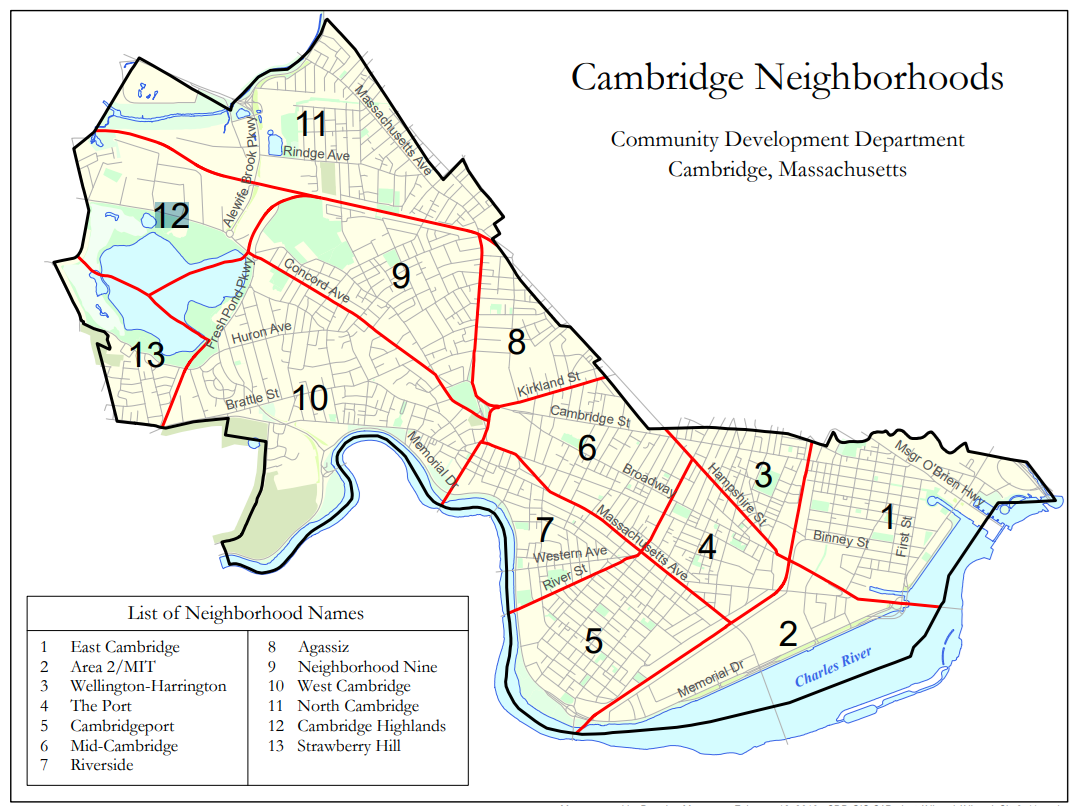

## **SEIR model, single neighborhood**

- One population with a single infected person, simulate from 0 to 100 days

- $\theta_{ij}$ = 0, no travel/commute from or to any other neighborhood

- $x_{sim,1}$ contains  $[S_1, E_1, I_1, R_1 ...S_P, E_P, I_P, R_P ]^T$ for all time

- $y_{sim,1}$ contains  $[\sum_{i=1}^{P} S_i,\;\;\sum_{i=1}^{P} E_i,\;\; \sum_{i=1}^{P} I_i,\;\;\sum_{i=1}^{P} R_i]^T$ for all time

% Simulation parameters
dt = 0.5;
numNeighborhoods = 1;
cases = {'noTravel','noMeasures','cutOffMultiple'};
stateInitType = {'singleInfectedAll', 'MIToutbreak'};

% Simulation
[ySim1, xSim1] = SimSEIR(numNeighborhoods, cases{1}, stateInitType{1}, dt);

Timestep 1, Time 0.50, Newton Iter 1, nf 7.070737e+00, ndx 7.141807e+00
Timestep 1, Time 0.50, Newton Iter 2, nf 6.564081e-05, ndx 6.796167e-05
Timestep 1, Time 0.50, Newton Iter 3, nf 2.699656e-11, ndx 2.798168e-11
Timestep 2, Time 1.00, Newton Iter 1, nf 7.070737e+00, ndx 7.141807e+00
Timestep 2, Time 1.00, Newton Iter 2, nf 6.564081e-05, ndx 6.796167e-05
Timestep 2, Time 1.00, Newton Iter 3, nf 2.699656e-11, ndx 2.798168e-11
Timestep 3, Time 1.50, Newton Iter 1, nf 7.214374e+00, ndx 7.919834e+00
Timestep 3, Time 1.50, Newton Iter 2, nf 4.217489e-04, ndx 4.366258e-04
Timestep 3, Time 1.50, Newton Iter 3, nf 1.820231e-10, ndx 1.884273e-10
Timestep 4, Time 2.00, Newton Iter 1, nf 8.625428e+00, ndx 1.003274e+01
Timestep 4, Time 2.00, Newton Iter 2, nf 1.044645e-03, ndx 1.081344e-03
Timestep 4, Time 2.00, Newton Iter 3, nf 4.500526e-10, ndx 4.658601e-10
Timestep 5, Time 2.50, Newton Iter 1, nf 1.143832e+01, ndx 1.373196e+01
Timestep 5, Time 2.50, Newton Iter 2, nf 2.331247e-03, ndx 2.412

Show the proportions of individuals in SEIR vs. time. Note that $y_{sim,1} = x_{sim,1}$ for the single neighborhood case.

Animate the SEIR trajectories.

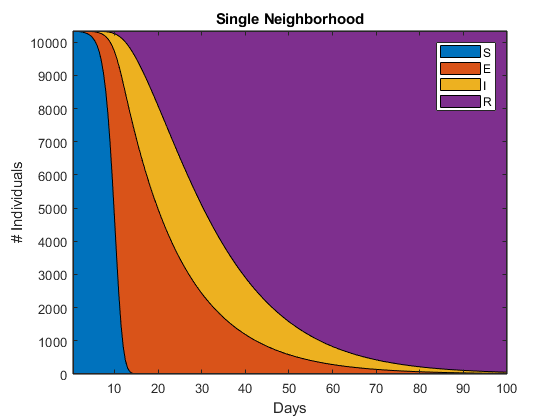

f1 = plotSEIRProp(ySim1,xSim1,dt);
formatFig(f1);

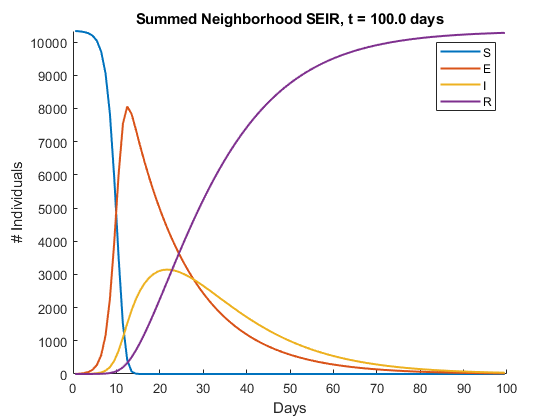

animationSpeed = 3;
pause;
f2 = animateSEIR(ySim1,animationSpeed);
formatFig(f2);

Calculate the maximum number of exposed and infected.

[maxEsim1, maxIsim1] = getMaxVals(xSim1);

Unrecognized function or variable 'xSim'.

fprintf('Sim 1: Max E = %5f \t Max I = %5f\n', maxEsim1, maxIsim1);

##  SEIR metapopulation (multiple neighborhoods) model, with travel

- 13 neighborhoods, single infected person in Neighborhood 2 (MIT)

- $\theta_{ij} \ne 0$, unrestricted travel/commute between neighborhoods

- Corresponds to little public health intervention

% Simulation parameters
numNeighborhoods = 13;

% Simulation
[ySim2, xSim2] = SimSEIR(numNeighborhoods, cases{2}, stateInitType{2}, dt);

Timestep 1, Time 0.50, Newton Iter 1, nf 1.345279e+01, ndx 5.970343e+00
Timestep 1, Time 0.50, Newton Iter 2, nf 3.405564e-03, ndx 2.363802e-03
Timestep 1, Time 0.50, Newton Iter 3, nf 2.382645e-08, ndx 1.632503e-08
Timestep 2, Time 1.00, Newton Iter 1, nf 1.345279e+01, ndx 5.970343e+00
Timestep 2, Time 1.00, Newton Iter 2, nf 3.405564e-03, ndx 2.363802e-03
Timestep 2, Time 1.00, Newton Iter 3, nf 2.382645e-08, ndx 1.632503e-08
Timestep 3, Time 1.50, Newton Iter 1, nf 3.508594e+00, ndx 3.077079e+00
Timestep 3, Time 1.50, Newton Iter 2, nf 2.304252e-04, ndx 1.584241e-04
Timestep 3, Time 1.50, Newton Iter 3, nf 1.707818e-09, ndx 1.125839e-09
Timestep 4, Time 2.00, Newton Iter 1, nf 2.660842e+00, ndx 2.341226e+00
Timestep 4, Time 2.00, Newton Iter 2, nf 4.097651e-05, ndx 3.044378e-05
Timestep 4, Time 2.00, Newton Iter 3, nf 3.039817e-10, ndx 1.950922e-10
Timestep 5, Time 2.50, Newton Iter 1, nf 2.074550e+00, ndx 2.057351e+00
Timestep 5, Time 2.50, Newton Iter 2, nf 1.471537e-05, ndx 1.231

Show the proportions of individuals in SEIR vs. time.

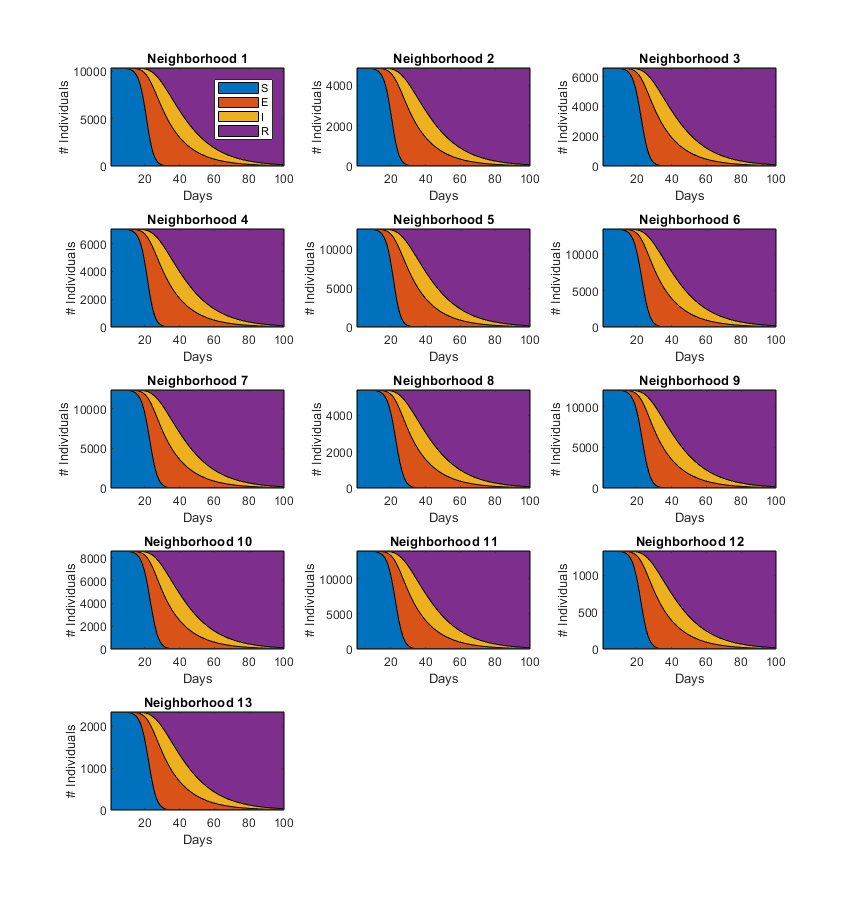

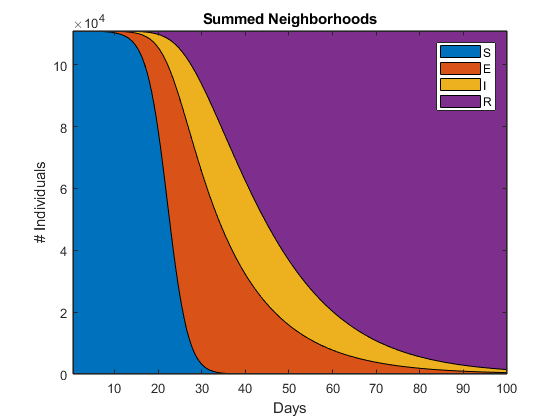

close all;
f3 = plotSEIRProp(ySim2,xSim2,dt);

Animate the SEIR trajectories.

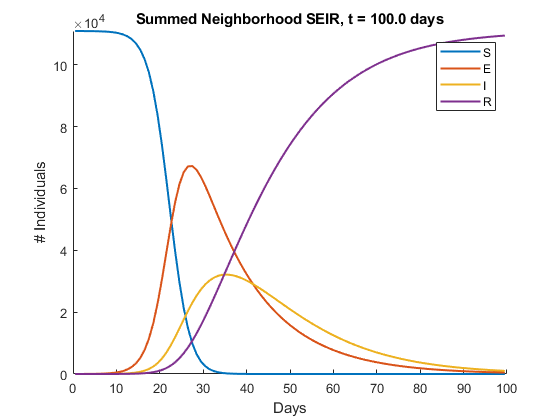

animationSpeed = 3;
pause();
f4 = animateSEIR(ySim2,animationSpeed);

formatFig(f3);
formatFig(f4);

Visualize  geographic spread.

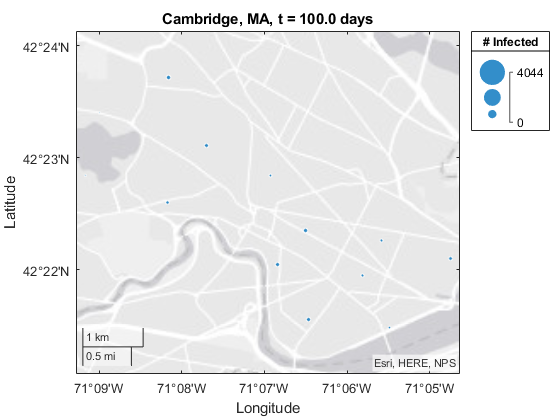

pause();

geovisSEIR(xSim2);

Calculate the maximum number of exposed and infected.

[maxEsim2, maxIsim2] = getMaxVals(ySim2);
fprintf('Sim 2: Max E = %5f \t Max I = %5f\n', maxEsim2, maxIsim2);

Sim 2: Max E = 7011.562768 	 Max I = 2997.532533


##  SEIR metapopulation model, with travel and neighborhood quarantine

- 12 neighborhoods, single infected person in Neighborhood 2

- $\theta_{ij} \ne 0$ except for neighborhoods 1,2 and 5, which are isolated (no travel/commute from or to any other neighborhood)

- Equivalent to zeroing out the 1st, 2nd, and 5th rows & columns in $\theta_{ij}$

- We hope to see a flattened curve for I.

% Simulation parameters
numNeighborhoods = 13;

% Simulation
[ySim3, xSim3] = SimSEIR(numNeighborhoods, cases{3}, stateInitType{2},dt);

Timestep 1, Time 0.50, Newton Iter 1, nf 7.064860e+00, ndx 7.080520e+00
Timestep 1, Time 0.50, Newton Iter 2, nf 1.103650e-04, ndx 1.137902e-04
Timestep 1, Time 0.50, Newton Iter 3, nf 9.131351e-11, ndx 9.377061e-11
Timestep 2, Time 1.00, Newton Iter 1, nf 7.064860e+00, ndx 7.080520e+00
Timestep 2, Time 1.00, Newton Iter 2, nf 1.103650e-04, ndx 1.137902e-04
Timestep 2, Time 1.00, Newton Iter 3, nf 9.131351e-11, ndx 9.377061e-11
Timestep 3, Time 1.50, Newton Iter 1, nf 7.097605e+00, ndx 7.733967e+00
Timestep 3, Time 1.50, Newton Iter 2, nf 8.307923e-04, ndx 8.564350e-04
Timestep 3, Time 1.50, Newton Iter 3, nf 6.865661e-10, ndx 7.049688e-10
Timestep 4, Time 2.00, Newton Iter 1, nf 8.369650e+00, ndx 9.671479e+00
Timestep 4, Time 2.00, Newton Iter 2, nf 2.043066e-03, ndx 2.105508e-03
Timestep 4, Time 2.00, Newton Iter 3, nf 1.692378e-09, ndx 1.737280e-09
Timestep 5, Time 2.50, Newton Iter 1, nf 1.096953e+01, ndx 1.309068e+01
Timestep 5, Time 2.50, Newton Iter 2, nf 4.490140e-03, ndx 4.625

Show the proportions of individuals in SEIR vs. time.

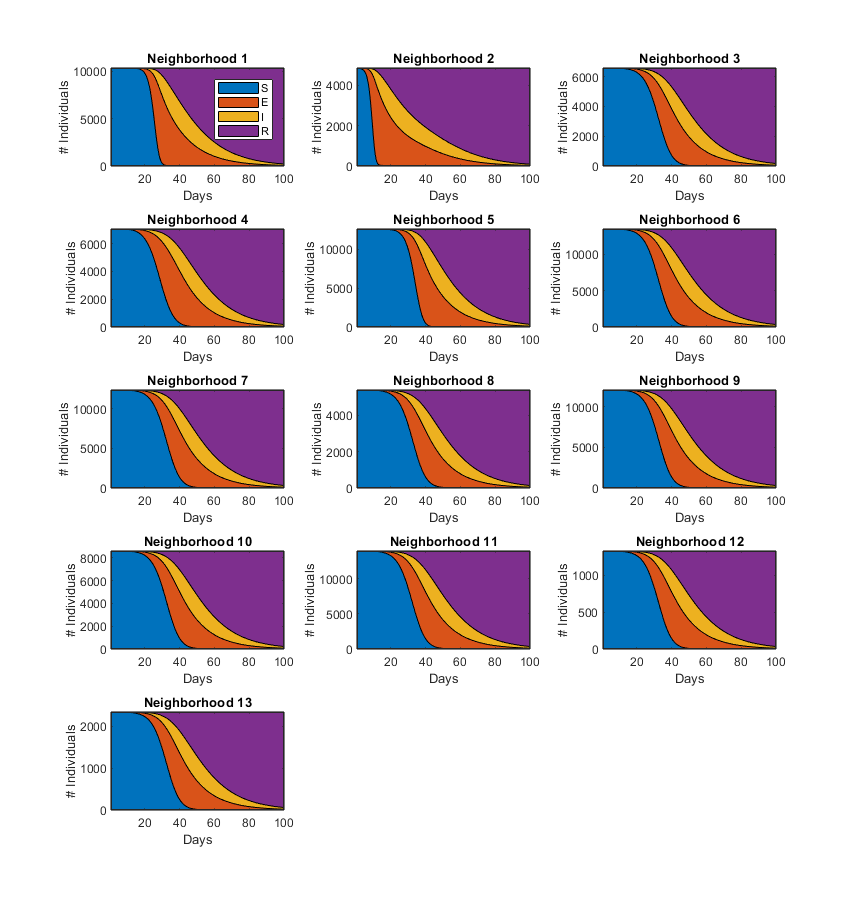

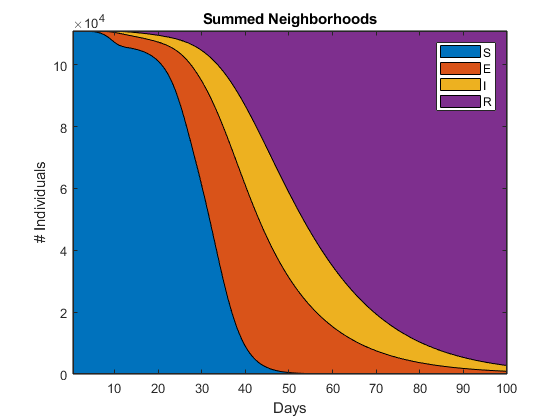

close all;
f5 = plotSEIRProp(ySim3,xSim3,dt);

Animate the SEIR trajectories.

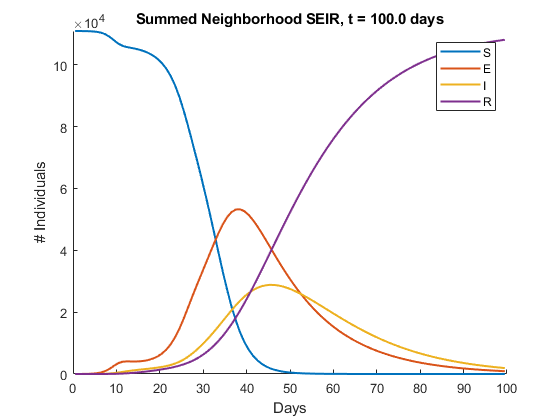

pause();
animationSpeed = 3;
f6 = animateSEIR(ySim3,animationSpeed);

formatFig(f5);
formatFig(f6);

Visualize  geographic spread.

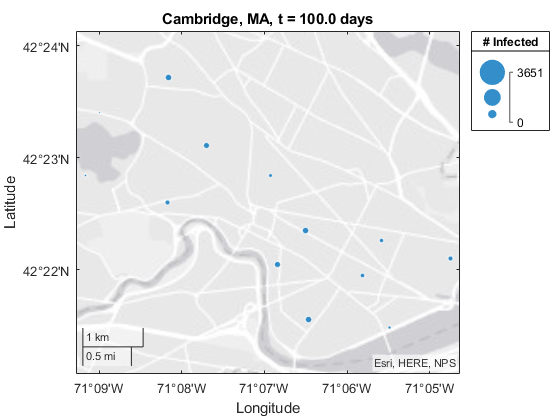

pause();
geovisSEIR(xSim3);

Calculate the maximum number of exposed and infected.

[maxEsim3, maxIsim3] = getMaxVals(ySim3);
fprintf('Sim 3: Max E = %5f \t Max I = %5f\n', maxEsim3, maxIsim3);

Sim 2: Max E = 7256.670893 	 Max I = 3042.933847
